%Crecimiento poblacion P(t)
%p'=rP(b-dP)
r=1;
b=0.1;
d=0.001;
p0=50;
tf=100;
f=@(t,p) r*p*(b-d*p);
[yHeun,xHeun]=odeHeun(f,0,p0,5,tf);
plot(xHeun,yHeun,'b')

syms P(t)
eqn=diff(P)==r*P*(b-d*P);
cnd=P(0)==p0;
Ps=dsolve(eqn,cnd)
fplot(Ps,[0 100])

%Ejercicio 2
%x'(t)=-(t/x)
t0=0;
x0=3; %r=3
syms X(t)
eqn2=diff(X)==-(t/X);
cnd2=X(0)==x0;
Xs=dsolve(eqn2,cnd2)
Xs2=-Xs
fplot(Xs,[-3 3])
hold on
axis('equal')
fplot(Xs2,[-3 3])
hold off

%Ejercicio 3
c0=0;
a0=4;
b0=1;
k=0.00713;
tf=400;
f3=@(t,c) (k(a0-c)^2)*(b0-(c/2));
[yHeun,xHeun]=odeHeun(f3,0,p0,5,tf);
plot(xHeun,yHeun,'b')

syms C(t)
eqn3=diff(C)== (k*(a0-C)^2)*(b0);
cnd3=C(0)==c0;
Xs=dsolve(eqn2,cnd2)
fplot(Xs)

Pruebas de ODE para sistemas

Presa-Depredador

tic
alpha=0.4;
beta=0.018;
delta=0.023;
gamma=0.8;
y0=[100;5];
tf=100;
h=0.25;
x0=[0;0];
%f1=@(t,y) alpha*y(1)-beta*y(1)*y(2)
%f2=@(t,y) delta*y(1)*y(2)-gamma*y(2)
%f=@(t,y) [f1(t,y);f2(t,y)];
f=@(t,y) [alpha*y(1)-beta*y(1)*y(2);delta*y(1)*y(2)-gamma*y(2)];
[yRK4,xRK4]=odeRK4(f,x0,y0,h,tf)
plot(xRK4,yRK4)
toc

Ahora simbolico

tic
alpha=0.4;
beta=0.018;
delta=0.023;
gamma=0.8;
y0=[30;4];
syms y1(t) y2(t)
y = [y1;y2]

ode1 = diff(y1)==alpha*y1-beta*y1*y2;
ode2 = diff(y2)==delta*y1*y2-gamma*y2;
odes = [ode1;ode2]

cond1=y1(0)==30;
cond2=y2(0)==4;
conds = [cond1;cond2];

[y1G,y2G] = dsolve(odes)
[y1P, y2P] = dsolve(odes,conds)

fplot(y1P)
hold on
fplot(y2P)
hold off
legend("y1", "y2")
%axis([0 2 0 10])
toc

Mas pruebas de sistemas

%f=@(t,y) [-0.5*y(1);
%    4-0.3*y(2)-0.1*y(1)];
M=[-0.5 0;-0.1 -0.3];
b=[0;4];
f=@(t,y) M*y+b; %Esta Matriz nos va a servir bastante
% Solo la podemos sacar para sistemas lineales con coeficientes constantes
% Con los eigenvalores vamos a poder analizar estas madres
h=0.5;
t0=-5;
tf=5;
y0=[4;6];
[yRK4,xRK4]=odeRK4(f,t0,y0,h,tf);
plot(xRK4,yRK4)
xlabel('t')
hold on
[yHeun,xHeun]=odeHeun(f,t0,y0,h,tf);
plot(xHeun,yHeun)
[yEuler,xEuler]=odeEuler(f,t0,y0,h,tf);
plot(xEuler,yEuler)
legend('y1 RK4','y2 RK4','y1 Heun','y2 Heun','y1 Euler','y2 Euler')
hold off

Ahora resolveremos este sistema de manera simbólica

syms y1(t) y2(t)
y=[y1;y2];
M=[-0.5 0;-0.1 -0.3];
b=[0;4];
odes=diff(y)==M*y+b
[y1G,y2G]=dsolve(odes)
y0=[4;6];
conds=y(0)==y0
[y1P,y2P]=dsolve(odes,conds)
fplot([y1P,y2P])

%Otra manera simbolica
syms y1(t) y2(t)
ode1=diff(y1)==-0.5*y1;
ode2=diff(y2)==4-0.3*y2-0.1*y1;
cond1=y1(0)==4;
cond2=y2(0)==6;
odes=[ode1;ode2];
[y1G,y2G]=dsolve(odes)
y0=[4;6]
conds=[cond1;cond2]
[y1P,y2P]=dsolve(odes,conds)
fplot([y1P,y2P],[0 2])

Otro ejercicio

tic
M=[3 -2;2 -2];
f=@(t,y) M*y;
h=0.1;
t0=0;
tf=2;
y0=[1;-1];
[yRK4,xRK4]=odeRK4(f,t0,y0,h,tf);
plot(xRK4,yRK4)
xlabel('t')
hold on
[yHeun,xHeun]=odeHeun(f,t0,y0,h,tf);
plot(xHeun,yHeun)
[yEuler,xEuler]=odeEuler(f,t0,y0,h,tf);
plot(xEuler,yEuler)
legend('y1 RK4','y2 RK4','y1 Heun','y2 Heun','y1 Euler','y2 Euler')
hold off
toc
eig(M)
%Ahora simbólico
tic
syms y1(t) y2(t)
y=[y1;y2];
M=[3 -2;2 -2];
odes=diff(y)==M*y
[y1G,y2G]=dsolve(odes)
y0=[1;-1];
conds=y(0)==y0
[y1P,y2P]=dsolve(odes,conds)
fplot([y1P,y2P],[0 2])
toc
%Checar que los valores propios están en las funciones simbólicas de y y z
%como exponentes.
% Los valores propios nos dan el comportamiento de estas funciones.

tic
M=[1 1;-1 1];
f=@(t,y) M*y;
h=0.1;
t0=0;
tf=2;
y0=[1;-1];
[yRK4,xRK4]=odeRK4(f,t0,y0,h,tf);
plot(xRK4,yRK4)
xlabel('t')
hold on
[yHeun,xHeun]=odeHeun(f,t0,y0,h,tf);
plot(xHeun,yHeun)
[yEuler,xEuler]=odeEuler(f,t0,y0,h,tf);
plot(xEuler,yEuler)
legend('y1 RK4','y2 RK4','y1 Heun','y2 Heun','y1 Euler','y2 Euler')
hold off
toc
eig(M)
%Ahora simbólico
tic
syms y1(t) y2(t)
y=[y1;y2];
M=[1 1;-1 1];
odes=diff(y)==M*y
[y1G,y2G]=dsolve(odes)
y0=[1;-1];
conds=y(0)==y0
[y1P,y2P]=dsolve(odes,conds)
fplot([y1P,y2P],[0 2])
toc

17 abril 2023

Resolver simbolicamente dy/dt=ky

syms y(t) k
ode=diff(y)==k*y
[yG]=dsolve(ode)
% Es una solucion general porque depende del valor de C1
% Cuando le damos un valor a y(0) es particular

% Formulas que usabamos en física
syms x(t) v(t) x0 v0 a
ode=diff(x,2)==a
Dx=diff(x)
cond1=Dx(0)==v0
cond2=x(0)==x0
conds=[cond1;cond2]
xG=dsolve(ode,conds)

%Ejercicio pendulo
% Matlab no debería de encontrar la solución simbólica
%Probable pregunta de exámenes
syms theta(t) g l 
ode=diff(theta,2)==-(g/l)*sin(theta)
Dtheta=diff(theta)
cond=Dtheta(0)==0
xG=dsolve(ode,cond)

syms theta(t) g l 
ode=diff(theta,2)==-(g/l)*theta
Dtheta=diff(theta);
cond=Dtheta(0)==0;
thetaG=dsolve(ode,cond)
%Para que lo exprese en compleja
rewrite(thetaG,'cos')

%Ahora usando odes numericos
%y=[theta;omega]
y0=[pi/8;0];
g=9.81;
l=1;
f=@(t,y) [y(2);(-g/l)*sin(y(1))];
t0=0

t0 = 0

T=2*pi*sqrt(l/g); %Es el periodo de oscilación ish
tf=8*T;
hEuler=0.0001;
[tEuler,yEuler]=TerPar_RK4(f, t0,y0,h,tf)

tEuler =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yEuler =     0.3927    0.3741    0.3199    0.2351    0.1277    0.0079   -0.1127   -0.2223   -0.3105   -0.3690   -0.3924   -0.3785   -0.3287   -0.2474   -0.1424   -0.0236    0.0976    0.2092    0.3007    0.3633    0.3914    0.3823    0.3369    0.2594    0.1569    0.0392   -0.0823   -0.1958   -0.2904   -0.3571   -0.3898   -0.3856   -0.3447   -0.2709   -0.1711   -0.0548    0.0669    0.1820    0.2796    0.3503    0.3876    0.3882    0.3519    0.2820    0.1851    0.0703   -0.0513   -0.1680   -0.2684   -0.3430
         0   -0.3697   -0.7058   -0.9766   -1.1549   -1.2218   -1.1700   -1.0052   -0.7449   -0.4155   -0.0483    0.3233    0.6656    0.9464    1.1378    1.2197    1.1832    1.0321    0.7828    0.4607    0.0964   -0.2765   -0.6243   -0.9147   -1.1190   -1.2157   -1.1944   -1.0574   -0.8195   -0.5051   -0.1445    0.2292    0.5821    0.8816    1.0983    1.2097    1.2037    1.0811    0.8549    0.5487    0.1923   -0.1816   -0.5391   -0.8471   -1.0759   -1.2018   -1.2111   -1.1029   -0.8890

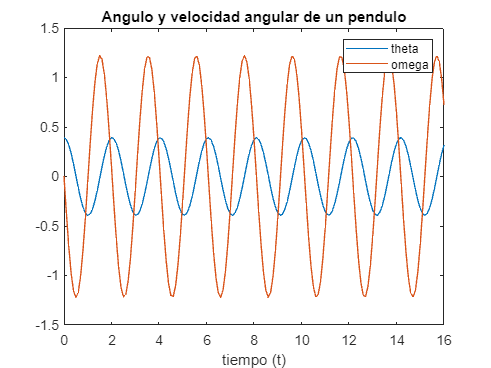

plot(tEuler,yEuler)
legend('theta','omega')
title('Angulo y velocidad angular de un pendulo')
xlabel('tiempo (t)')

Para ecuaciones de segundo orden las convertimos en primer orden

y''+y'-2y=0

Es lineal homogénea

Primero necesitamos pasarla a dos ecuaciones de primer orden

Para eso Z=y'   =>    Z'=y''

[y';z']=[0 z;2y -z]

(yz)'=M*yz

Si fuera de tercer orden 

ZZ=y''

M=[0 1;2 -1];
f=@(t,yz) M*yz;
h=0.1;
t0=0;
tf=1;
y0=[3;0];
[yRK4,xRK4]=odeRK4(f,t0,y0,h,tf);
plot(xRK4,yRK4(1,:))
xlabel('t')
legend('Valores de y')
eig(M)

Ahora 3y'' +18y'+102y=10

En este caso b=[0;10] porque es constante

Si estuviera igualado a una funcion b=[0;f]

M=[0 1;-34 -6];
b=@(t) [0;10/3];
f=@(t,yz) M*yz+b(t);
h=0.01;
t0=0;
tf=5;
yz0=[0;0];
[yz,t]=odeRK4(f,t0,yz0,h,tf);
plot(t,yz(1,:))
title("eqn: 3y''+18y'+102y=10")
xlabel('t')
legend('Valores de y')

Ahora x''' + x=0

x(0)=0   x'(0)=1   x''(0)=0   tf=10

M=[0 1 0;0 0 1;-1 0 0];
b=@(t) [0;0;0];
f=@(t,yz) M*yz+b(t);
h=0.1;
t0=0;
tf=10;
xz0=[0;1;0];
[yz,t]=odeRK4(f,t0,xz0,h,tf);
plot(t,yz(1,:))
title("eqn: x''' + x = 0")
xlabel('t')
legend('Valores de x')

26 abril 2023

f=@(t,y) (1/2)*(1+t).*(y.^2)
y0=1;
t0=0;
tf=1;
h=0.05;
[t, y] = TerPar_AMB4(f,y0,t0,tf,h)
plot(t, y)

f=@(t,y) (1/2)*(1+t).*(y.^2)

f = function_handle with value:
    @(t,y)(1/2)*(1+t).*(y.^2)


y0=1;
t0=0;
tf=1;
h=0.05;
[t, y] = TerPar_EullerImplicit(f,y0,t0,tf,h)


t =

  1×0 empty double row vector



y = 0.0500

plot(t, y)

Error using plot
Vectors must be the same length.